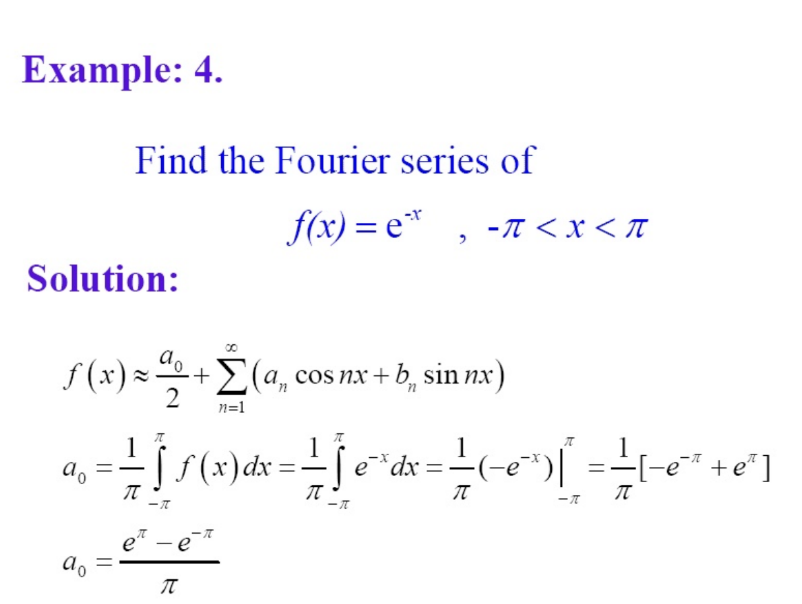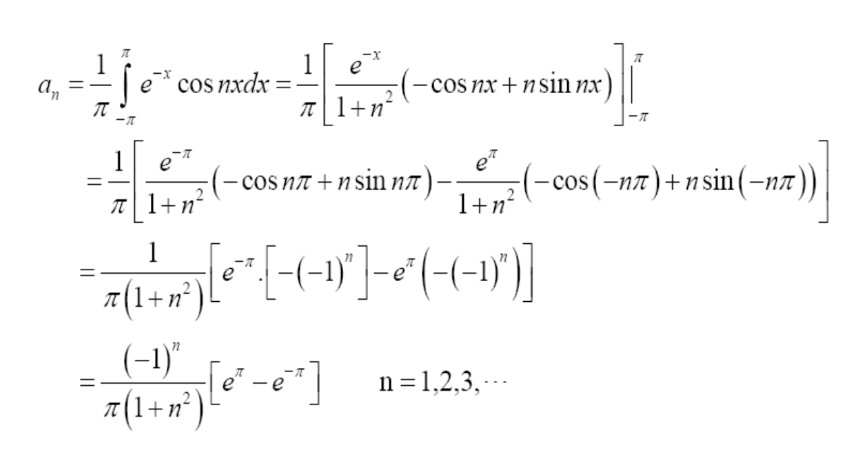

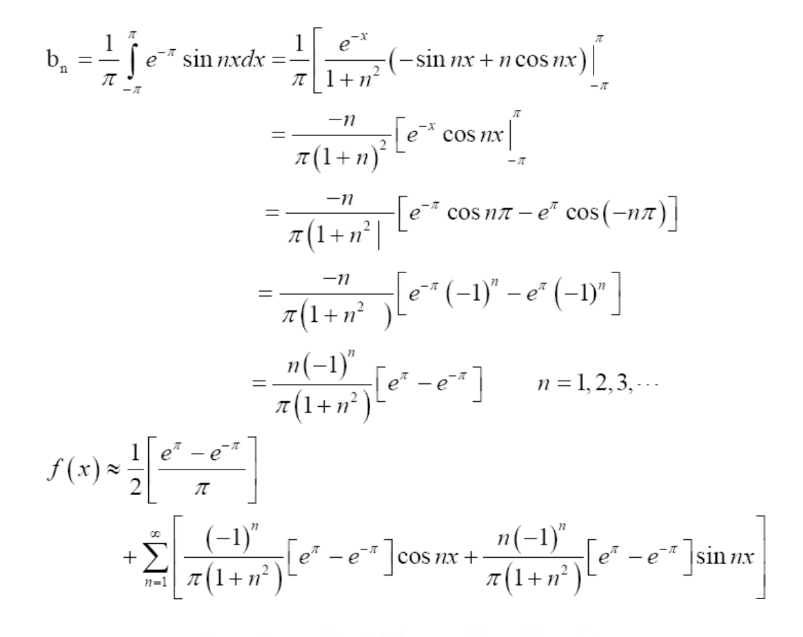

clear
clc
syms x n Sigma;
f = exp(-x);
a0 = eval((1/pi)*int(f,x,[-pi pi]))

a0 = 7.3522

assume(n,"integer")
an = vpa(simplify((1/pi)*int(f*cos(n*x),x,[-pi pi])),3)

$$an = \frac{7.35\,{\left(-1.0\right)}^{n}}{n^{2}+1.0}$$

bn = vpa(simplify((1/pi)*int(f*sin(n*x),x,[-pi pi])),3)

$$bn = -\frac{7.35\,{\left(-1.0\right)}^{n+1.0}\,n}{n^{2}+1.0}$$

f0 = vpa(simplify(an*cos(n*x)+bn*sin(n*x)),3)

$$f0 = \frac{7.35\,{\left(-1.0\right)}^{n}\,\left(\cos\left(n\,x\right)+n\,\sin\left(n\,x\right)\right)}{n^{2}+1.0}$$

fn =symsum(simplify(an*cos(n*x)+bn*sin(n*x)),n,1,inf)

$$fn = 7.3521558206994086503982543945312\,\left(\sum_{n=1}^{\infty }\frac{{\left(-1.0\right)}^{n}\,\left(\cos\left(n\,x\right)+n\,\sin\left(n\,x\right)\right)}{n^{2}+1.0}\right)$$

f = vpa((a0/2+fn),3)

$$f = 7.35\,\left(\sum_{n=1}^{\infty }\frac{{\left(-1.0\right)}^{n}\,\left(\cos\left(n\,x\right)+n\,\sin\left(n\,x\right)\right)}{n^{2}+1.0}\right)+3.68$$

harm = 3; 

**Plot graphs**

for i = 1:harm
    fx = a0/2+symsum(f0,n,[1 i]);
    subplot(harm+1,1,i)
    fplot(fx,[-pi pi])
    title('Harmonic')
    xlabel('time')
end
hold on

**Plot Input**

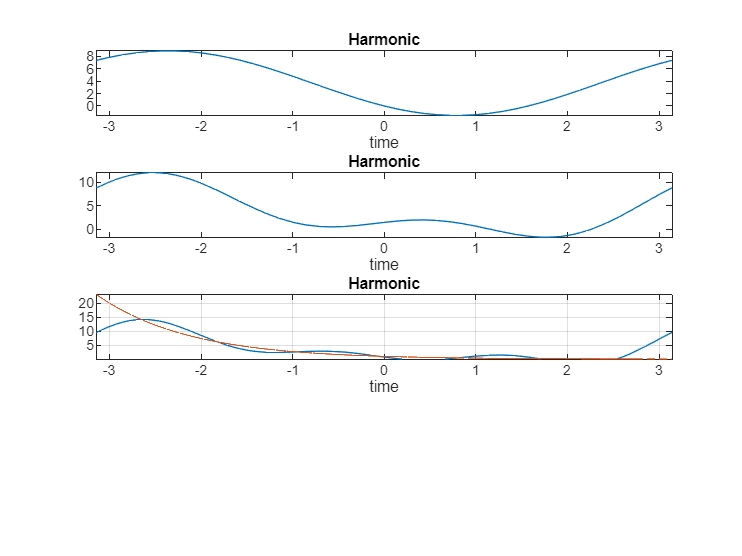

t = -pi:1/1000:pi;
y = exp(-t);
plot(t,y)
ylim([exp(-pi) exp(pi)])
grid on

**Spectrum plot**

i = 1:harm;
mg = eval(sqrt(subs(an,n,i).^2+subs(bn,n,i).^2));
mag = [a0/2 mg]

mag =     3.6761    5.1988    3.2880    2.3250


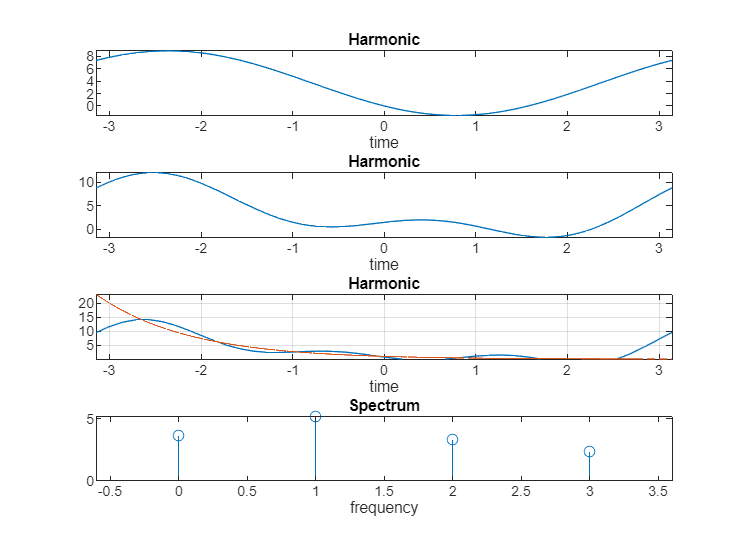

subplot(harm+1,1,harm+1)
stem([0 i],mag)
title('Spectrum')
xlabel('frequency')